**Co**ntinuation of **S**olution **T**orus **A**pp**R**oximations

[Engineering Dynamics Group, Institute for Mechanics, University of Kassel, Germany](https://www.uni-kassel.de/maschinenbau/institute/mechanik/fachgebiete/technische-dynamik/startseite)

# Tutorial: Postprocessing Functions

### Welcome to the CoSTAR Tutorials!

In this tutorial, we will look at the three postprocessing functions `contplot`, `solplot` and `solget` and how to use them. Of course, we need a solution computed by CoSTAR before we can use the postprocessing functions, so we start with a continuation in order to have a set of solutions at hand. After that, we will have a detailed look at each postprocessing function. The corresponding sections on the postprocessing methods can be worked through independently.

### Computing solutions to work with

In this tutorial, we use the periodically forced *Duffing* oscillator $x^{\prime\prime} + 2Dx{\prime} + x + \kappa x^3 = g \cos (\eta \tau)$ as an example. The continuation parameter $\mu$ will be the excitation frequency $\eta$ and we will use the shooting method to approximate the solutions.

Before we can use CoSTAR, we need to add the main CoSTAR folder (and all subfolders) to MATLAB's search path. Assuming you are running this script within the *Tutorials* subfolder of CoSTAR, this is done by:

% addpath(genpath('..\'))           % genpath() generates a search path containing all subfolders

(Note: The command above is set as comment in order to prevent unwanted folders to be added to MATLAB's search path in case that the current path is not the *Tutorials* subfolder.)

Now we are set to perform a continuation of the periodically forced *Duffing* oscillator using the shooting method. The following code is taken from *Example_PS_SHM *and not explained any further at this point. If you are new to CoSTAR, it is advised to go through the corresponding example within the tutorial on periodic solutions approximated by the shooting method (see *Tutorial_PS_SHM*, chapter 1) before continuing with this tutorial.


                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          4           0.0292105                           0.171              1
     1          8           3.649e-18       0.170911         1.42e-09              1

Equation solved. The sum of squared function values, r = 3.648999e-18, is less than
sqrt(options.FunctionTolerance) = 1.000000e-03. The relative norm of the gradient of r,
1.423941e-09, is less than options.OptimalityTolerance = 1.000000e-06.

-------------------------------------------------------
--------------- Initial solution found! ---------------
-------------------------------------------------------
Iter: 2 -- mu = 0.1100 -- stepwidth = 0.1000
Iter: 3 -- mu = 0.1642 -- stepwidth = 0.0500
Iter: 4 -- mu = 0.1729 -- stepwidth = 0.0250
Iter: 5 -- mu = 0.1903 -- stepwidth =

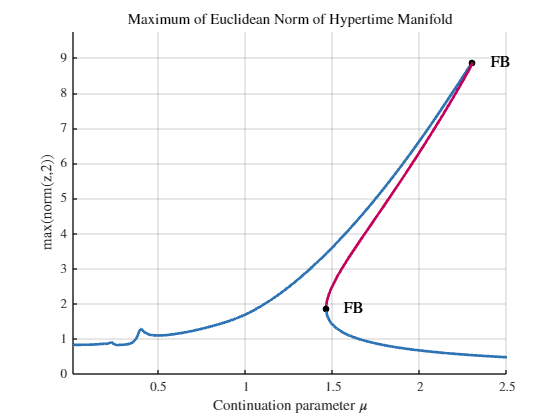

clear variables; clc; close all;                    % clear workspace; clear command window; close all figures

% Parameters
D = 0.05;     kappa = 0.3;     g = 1;               % Parameters needed for the Duffing differential equation
mu_limit = [0.01, 2.5];                             % Limits of the continuation        
eta0 = mu_limit(1);                                 % Value of continuation parameter at start of continuation
param = {kappa, D, eta0, g};                        % Parameter array
active_parameter = 3;                               % Location of continuation parameter within the array
IC = [1; 0];                                        % Initial condition (point in state space) for fsolve

% Functions
non_auto_freq = @(mu) mu;                           % Non-autonomous excitation frequency
Fcn =  @(t,z,param) duffing_ap(t,z,param);          % Right-hand side of dz/dtau = f(tau,z,kappa,D,eta,g)

% Options
options.system = costaropts('order',1,'dim',2,'rhs',Fcn,'param',param,'info','continuation of Duffing equation');   % Properties of the system
options.opt_sol = costaropts('sol_type','periodic','approx_method','shooting','cont','on','stability','on', ...     % Properties of the solution
                             'non_auto_freq',non_auto_freq,'act_param',active_parameter);                           % Properties of the solution
options.opt_init = costaropts('ic',IC);                                                                             % Property for initial solution
options.opt_approx_method = costaropts('solver','ode45');                                                           % Properties of approximation method
options.opt_cont = costaropts('mu_limit',mu_limit);                                                                 % Properties for continuation

% Continuation
[S,DYN] = costar(options);                          % CoSTAR is called by costar(options)

Alright, now we have enough solutions to work with.

# `contplot`

As the name suggests, the postprocessing function `contplot` is used to create continuation diagrams (or bifurcation diagrams) in which the solution is plotted with respect to the continuation parameter (or bifurcation parameter) $\mu$. For example, the default plot which CoSTAR displays during a continuation is such a diagram.

## General syntax

`contplot` is used in the following way:

#### **Input arguments**

- `DYN`**:** `DynamicalSystem` object returned by the `costar` function. Must correspond to `Solution` object `S`, which is also returned by the `costar` function.

- `contplot_options`**:** Structure defining the necessary options. Must be created using the `costaropts` function. In case of any invalid entry, the CoSTAR *Gatekeeper* will throw an error.

**Output arguments**

- `z_val:` Ordinate (vertical axis) values. These are the (usually) postprocessed and plotted solution values with respect to $\mu$.

- `mu_val:` Abscissa (horizontal axis) values. These are the $\mu$-values of the plotted solutions.

As you can see, the general syntax is quite easy. The available options, however, are a bit more tricky. 

## Options

All settings for `contplot` are defined via a structure array. This structure array must be created using the `costaropts` function, which is also used to create the general `options` structures for CoSTAR (see the example in the section **Computing solutions to work with **above). [*Reminder: The syntax of the input arguments of *`costaropts`* is equivalent to the MATLAB struct function, i.e. *`costaropts('fieldname1',fieldvalue1,...,'fieldnameN',fieldvalueN)`*.*] Similar to the general `options` structure, there is a mandatory field which always has to be definied. Apart from that, there are optional fields which can be set. Most of the optional fields have a default value. 

Let us have a look at the particular fields.

#### **Mandatory field**

So what does that mean? Let us call $x (\theta)$ the solution of the aformentioned *Duffing* equation and $x^{\prime} (\theta)$ its derivative, where $\theta \in [ 0, 2\pi )$ is the hypertime domain. Since CoSTAR uses the state space representation of a differential equation in combination with the hypertime parametrization approach, CoSTAR computes the state vectors $\textbf z_{\text{P}} (\theta) = [x(\theta) \;\;x^{\prime} (\theta) ]^\top$ (P: periodic) of a solution. When specifying `'max2'` for `'zaxis'`, mathematically speaking,$\max_{\theta \in [ 0, 2\pi )} \Vert \mathbf z_{\text{P}}(\theta)\Vert$ is plotted on the ordinate axis. The evaluation is effectively done for all computed state vectors $\textbf z_{\text{P}} (\theta=\theta_i)$ of a solution. The number of state vectors that are used for the evaluation are controlled by the field `'resolution'` (see below). When defining `'min2'` or `'mean2'` for `'zaxis'`, the postprocessing is done in a similar way, but the minimum or the mean of $\Vert \mathbf z_{\text{P}}(\theta)\Vert$ is used.

For quasi-periodic solutions $\mathbf z_{\text{QP}} (\theta_1,\theta_2) = \mathbf z_{\text{QP}} (\mathbf \theta)$, the method described above is applied in an analogous manner, but the minimum, mean or maximum is evaluated on the hypertime domain $\mathbf\theta \in [ 0, 2\pi )^2$. For equilibrium solutions $\mathbf z_{\text{EQ}}$ (single points in state space), only $\Vert \mathbf z_{\text{EQ}} \Vert$ is computed since applying the minimum, mean or maximum on $\Vert \mathbf z_{\text{EQ}} \Vert$ has no effect.

After having discussed `'min2'`, `'mean2'` and `'max2'`, let us turn to function handles, which can be used to create an individual continuation plot. The function handle has to map a solution $\mathbf z_{\text{EQ}}$, $\textbf z_{\text{P}} (\theta)$ or $\mathbf z_{\text{QP}} (\mathbf \theta)$ to a scalar value that is used in the bifurcation diagram. Due to different parametrisations of the different solution types (no parametrisation required for equilibrium solutions, whereas periodic solutions are parametrised using $\theta$ and quasi-periodic solutions are parametrised using $\mathbf\theta = \left(\theta_1,\;\theta_2\right)$), the input argument and therefore the required syntax changes depending on the solution type.

To summarise, the input array is either one-, two- or three-dimensional and the elements of the computed state vectors can be accessed via the last array dimension, while the other array dimensions correspond to the hypertime coordinates. 

Next, we take a closer look at the optional fields available for `contplot`.

#### **Optional fields**

It is pointed out again that all of the optional fields do not have to be set. In case a field is left out, its default value is used. 

When you just need a quick overview on the available fields of `contplot` in future, you can use the `costarhelp` feature. Typing 

in the command window will display the mandatory and optional fields, their allowed values and a short description for each available field.

Now we have discussed all available option structure fields of `contplot`. To finish the section on contplot, we consider a few examples.

## Examples

#### Continuation Plot

First, let us recreate the continuation plot. As you may have noticed in the continuation diagram of our exemplary continuation (see section **Computing solutions to work with **above), CoSTAR automatically plots `max(norm(z,2))` on the ordinate axis. Mathematically, this translates to $\max_{\theta \in [ 0, 2\pi )} \Vert \mathbf z_{\text{P}}(\theta)\Vert$ when considering periodic solutions. Therefore, the mandatory options field `'zaxis'` must be set to `'max2'` in order to recreate the continuation plot. All of the optional fields can be left out since their default values are used automatically when performing a continuation. Thus, we define the necessary option structure only using the field `'zaxis'` and invoke the `contplot` method using the objects `DYN` and `S` from the continuation above:

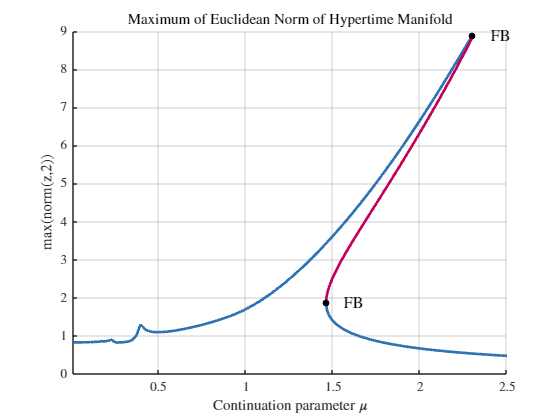

contplot_options = costaropts('zaxis','max2');
[z_val,mu_val] = S.contplot(DYN,contplot_options); 

Keep in mind that `contplot` returns the abscissa values (`mu_val`) and ordinate values (`z_val`) of the plotted points, which can be further used for individual purposes.

#### Maximum absolute value of the state variables

Next, we want to have a look at the maximum absolute value of $x(\theta)$ and its derivative $x'(\theta)$. According to the explanation of the options field `'zaxis'` above, we obtain the maximum absolute value of $x(\theta)$ via the function handle `@(z) max(abs(z(:,1)))`. For the maximum absolute value of $x'(\theta)$, we need to specify  `@(z) max(abs(z(:,2)))`. Additionally, we want to plot both of the curves into the same figure and depict them in different colours and line styles.

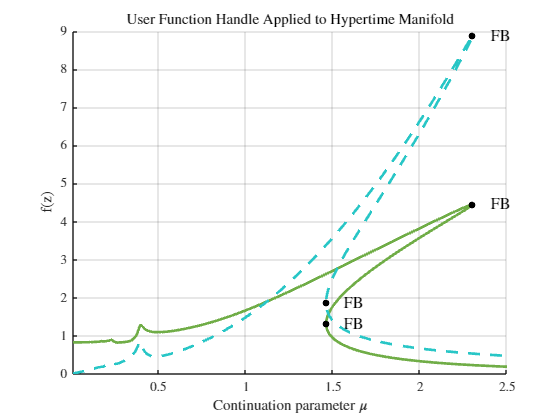

% Plot the maximum absolute value of x(theta) = z_1(theta) in green:
contplot_options_1 = costaropts('zaxis',@(z) max(abs(z(:,1))),'color','g');     
[z_val_1,mu_val_1] = S.contplot(DYN,contplot_options_1);
% Plot the maximum absolute value of x'(theta) = z_2(theta) in magenta and as dashed line into the same figure:
contplot_options_2 = costaropts('zaxis',@(z) max(abs(z(:,2))),'color','c','linestyle','--','figure',gcf);     
[z_val_2,mu_val_2] = S.contplot(DYN,contplot_options_2);

#### Section of continuation curve using different resolution

As a third example, let us assume that we are especially interested in the solutions near the "upper" bifurcation point at $\mu \approx 2.3$. Analysing the property `bifurcation` of the `Solution` object `S`, we find the mentioned bifurcation point to be the $162$-th solution stored in S. Thus, we select the solutions of index number $155$ to $170$ for our new plot. Since the selected solutions are of special interest for us, we aim at a high accuracy of the continuation curve, so we define a high resolution.

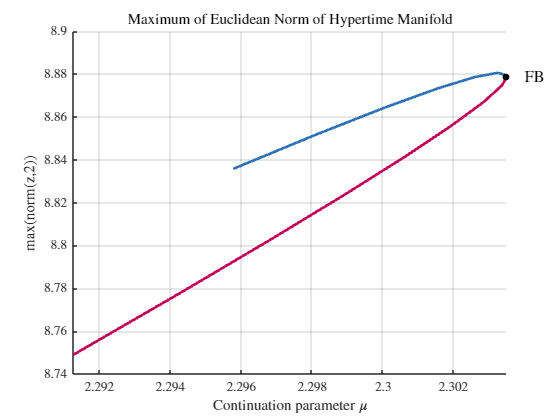

contplot_options_3 = costaropts('zaxis','max2','index',155:170,'resolution',500);     
[z_val_3,mu_val_3] = S.contplot(DYN,contplot_options_3);
xlim([min(mu_val_3) max(mu_val_3)])     % We need to adapt the abscissa limits since contplot uses the limits of the continuation parameter mu per default

That's it! Now you now how to use the `contplot` method. Going on, we take a closer look at the postprocessing method `solplot`.

# `solplot`

The postprocessing function `solplot` is used to display individual solutions in different *"solution spaces"*. In particular, four different solution spaces are available:

- ***Time*****:**              The solution is plotted with respect to time $t$

- ***Hypertime*****:**     The solution is displayed with respect to hypertime $\theta$ (periodic case) or $\mathbf\theta = \left(\theta_1,\;\theta_2\right)$ (quasi-periodic case)

- ***Trajectory*****:   **  The trajectory of a solution is plotted in state space or in a corresponding subspace (2D or 3D respectively)

- ***Frequency*****:**    The frequency content of a solution is displayed

In the following, we will focus on periodic and quasi-periodic solutions. Although `solplot` could theoretically be used for equilibrium solutions as well, it does not really make sense to consider this case since equilibrium solutions depicted in the available solution spaces result in very trivial plots.

## General syntax

`solplot` is used in the following way:

#### **Input arguments**

- `DYN`**:** `DynamicalSystem` object returned by the `costar` function. Must correspond to `Solution` object `S`, which is also returned by the `costar` function.

- `solplot_options`**:** Structure defining the necessary options. Must be created using the `costaropts` function. In case of any invalid entry, the CoSTAR *Gatekeeper* will throw an error.

**Output arguments**

The four output arguments depend on the selected solution space in which the solution is displayed. 

The specific meaning of the ordinate values and of the depicted trajectory(s) in state space depend on the requested quantity to plot (defined via the options field `'zaxis'`, see below). For instance, this can be the first state variable $z_1$ or, in case of a 2D trajectory plot, the state variables $z_1$ and $z_2$. Moreover, the individual array sizes of the different outputs depend on the solution type (periodic or quasi-periodc), the requested quantity to plot and the number of different solutions to plot. Details are explained in the next section.

## Options

All settings for `solplot` are defined via a structure array. This structure array must be created using the `costaropts` function, which is also used to create the general `options` structures for CoSTAR (see the example in the section **Computing solutions to work with **above). [*Reminder: The syntax of the input arguments of *`costaropts`* is equivalent to the MATLAB struct function, i.e. *`costaropts('fieldname1',fieldvalue1,...,'fieldnameN',fieldvalueN)`*.*] Similar to the general `options` structure, there are mandatory fields which always has to be definied. Apart from that, there are optional fields which can be set. Most of the optional fields have a default value. 

Let us have a look at the particular fields.

#### **Mandatory fields**

So what does that mean? Let us call $x (\theta)$ the solution of the aformentioned *Duffing* equation and $x^{\prime}(\theta)$ its derivative. Since CoSTAR uses the state space representation of a differential equation in combination with the hypertime parametrization approach, CoSTAR computes the state vectors $\textbf z_{\text{P}} (\theta) = [x(\theta) \;\;x^{\prime} (\theta) ]^\top$ (P: periodic) of a solution. When specifying `'euclidean'` for `'zaxis'`, mathematically speaking,$\Vert \mathbf z_{\text{P}}(\theta)\Vert$ (*hypertime* solution space) or $\Vert \mathbf z_{\text{P}}(t)\Vert$ (*time* solution space) is plotted on the ordinate axis. In case of *frequency* solution space, a FFT of $\Vert \mathbf z_{\text{P}}(t)\Vert$ is carried out and its absolute amplitudes are plotted on the ordinate axis with respect to the angular frequency. When specifying `'all'` for `'zaxis'`, all state variables, i.e. all elements of $\textbf z_{\text{P}}$ ($x$ and $x^{\prime}$ in our example), are displayed separately in the selected solution space. This is also true for *frequeny* solution space where a FFT is carried out for each state variable separately.

For quasi-periodic solutions $\mathbf z_{\text{QP}} (\mathbf \theta) = \mathbf z_{\text{QP}} (\theta_1,\theta_2)$, the explanation above can be applied in an analogous manner. Please note that in case of *hypertime* solution space, the solution is depicted as 2D manifold (MATLAB surface plot) with respect to hypertime coordinates $\mathbf\theta = \left(\theta_1,\;\theta_2\right)$.

After having discussed `'euclidean'` and `'all'`, let us turn to function handles, which can be used to create an individual plot. Due to different parametrisations of possible solutions to plot, the input argument and therefore the required syntax changes depending on the solution space and the solution type.

As you can see, the function handle has to map a 2D-array to a vector valued output for most cases. This is because *time*, *periodic hypertime*, *trajectory* and *frequency* solution space plots are all based on a parametrisation in time or in scalar hypertime $\theta$, i.e. these solution plots are based on a one-dimensional parametrisation. The only exception are quasi-periodic hypertime plots, where the solution is parametrised in two-dimensional hypertime $\mathbf\theta = \left(\theta_1,\;\theta_2\right)$.

Next, we take a closer look at the optional fields available for `solplot`.

#### **Optional fields**

ES GEHT WEITER BEI RESOLUTION

It is pointed out again that all of the optional fields do not have to be set. In case a field is left out, its default value is used. 

When you just need a quick overview on the available fields of `contplot` in future, you can use the `costarhelp` feature. Typing 

in the command window will display the mandatory and optional fields, their allowed values and a short description for each available field.

Now we have discussed all available option structure fields of `contplot`. To finish the section on contplot, we consider a few examples.

- explanation of output argument array sizes